% user defined
fc = 2.4e+9;
% fc = 900e+6;
% fc = 899e+6;
fspan = 1e+7;


## Setup

Create SAPrams struct, comm.SDRRxPluto and `spectrumAnalyzer` object and configure based on user input

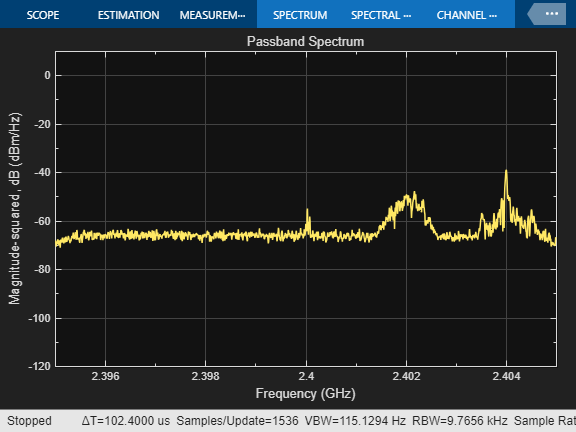


% from fspan, we can calculate the baseband sampling frequency needed
% for a two sided spectrum, the sampling rate needed = fspan
baseBandSampleRateRequired = fspan;

% create a SAParams struct to store setting for Spectrum Analyser
SAParams.isSourceRadio = 1;
SAParams.isSourcePlutoSDR = 1;
SAParams.CenterFrequency = fc;
SAParams.FrontEndSampleRate = baseBandSampleRateRequired;
SAParams.FrontEndFrameTime = 0.0100;

% release them if its from last run
if exist('sigSrc', 'var')
    release(sigSrc);
end

if exist('hSpectrum', 'var')
    release(hSpectrum);
end


% create a comm.SDRRxPluto object to receive from the sdr
sigSrc = sdrrx( ...
    'Pluto',...
    'RadioID',                  'usb:0',...
    'CenterFrequency',          fc,...
    'OutputDataType',           'single',...
    'BasebandSampleRate',       baseBandSampleRateRequired ...
);

% create spectrumAnalyzer object
hSpectrum = spectrumAnalyzer(...
    'Name',             'Passband Spectrum',...
    'Title',            'Passband Spectrum', ...
    'Method',           'Welch', ...
    'SpectrumType',     'Power density', ...
    'FrequencySpan',    'Full', ...
    'SampleRate',       SAParams.FrontEndSampleRate, ...
    'SpectralAverages', 50, ...
    'FrequencyOffset',  SAParams.CenterFrequency, ...
    'YLimits',          [-120 10], ...
    'YLabel',           'Magnitude-squared, dB', ...
    'Position',         figposition([50 30 30 40]));

## Stream processing

View the spectrum. While the spectrum analyzer is running, you can measure peaks, occupied bandwidth, and other properties of the signal.

% Initialize radio time
radioTime = 0;

% Main loop
% while radioTime < userInput.Duration
while radioTime < 1000
  % Receive baseband samples (Signal Source)
  if SAParams.isSourceRadio
      if SAParams.isSourcePlutoSDR
          rcv = sigSrc();
          lost = 0;
          late = 1;
      elseif SAParams.isSourceUsrpRadio
          rcv= sigSrc();
          lost = 0;
      else
          [rcv,~,lost,late] = sigSrc();
      end
  else
    rcv = sigSrc();
    lost = 0;
    late = 1;
  end

    rcv = rcv - mean(rcv);  % Remove DC component.
    step(hSpectrum, rcv);

  % Update radio time. If there were lost samples, add those too.
  radioTime = radioTime + SAParams.FrontEndFrameTime + ...
    double(lost)/SAParams.FrontEndSampleRate;
end

## Establishing connection to hardware. This process can take several seconds.
